# Controladores digitais com estrutura RST

## Maria Júlia de Oliveira Vieira

GitHub: https://github.com/JuliaOli/Controle-II.git

clear all
clc

Ts = 1;
num = [1];
den = [10 1];

G = tf(num, den)


G =
 
     1
  --------
  10 s + 1
 
Continuous-time transfer function.




G_z = c2d(G, Ts)


G_z =
 
   0.09516
  ----------
  z - 0.9048
 
Sample time: 1 seconds
Discrete-time transfer function.




% Polos das funcoes
num_g_z = cell2mat(G_z.Numerator);
den_g_z = cell2mat(G_z.Denominator);
den_g = cell2mat(G.Denominator);

%% Agora precisa achar os dados

%Calcular Polo desejado
pol = exp(-Ts/den_g(1))

pol = 0.9048


% encontrar os n's
n_a = length(den_g_z)-1;

n_b = length(num_g_z)-1;

d = length(num_g_z)-1;

n_r = n_b + d -1;
n_s = n_a - 1;

% Polinomio desejado
P = [1 -pol]

P =     1.0000   -0.9048



%Encontrando o R
R = P(1)

R = 1


%Encontrando o S
syms s
S = (num_g_z(2)*s + den_g_z(2)*R) == -pol;
solve_S = solve(S)

$$solve\_S = 0$$


S_s = 0;
% Encontrar T: P  = 1 - 0,9048 // B = 0,095 // T = P(1)/B(1)
T = (P(1) + P(2))/num_g_z(2);

%Funcao final
G_c =feedback(G_z*(1/R),S_s)


G_c =
 
   0.09516
  ----------
  z - 0.9048
 
Sample time: 1 seconds
Discrete-time transfer function.



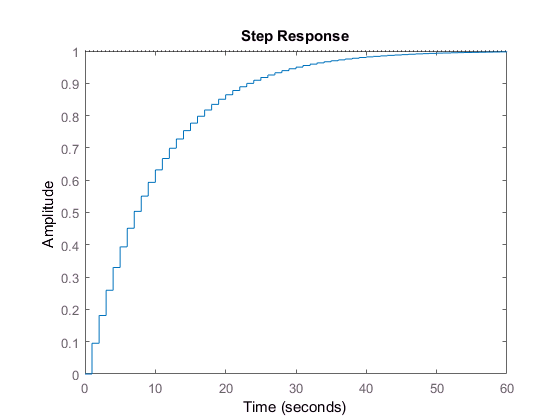

step(G_c)